读取数据

clc, clear,close all;

ref = zeros(1, 250000000);
sur = zeros(1, 250000000);
load(sprintf('data/data_%d.mat',1));

% 设计低通滤波器
[b, a] = butter(20, 9*10^6/(f_s/2),'low');

% 读取所有的文件，将下面改成for idx = 1:20
for idx = 1:20
    left = (idx - 1) * (12500000) + 1;
    right = idx * 12500000;
    load(sprintf('data/data_%d.mat',idx));

    % 频移（DDC）
    f_ddc=3e6;
    ref_shift=seq_ref.*exp(1i*2*pi*f_ddc*(0:1:length(seq_ref)-1)/f_s);
    sur_shift=seq_sur.*exp(1i*2*pi*f_ddc*(0:1:length(seq_sur)-1)/f_s);

    % 低通滤波（LPF）
    ref_filter = filter(b,a,ref_shift);
    sur_filter = filter(b,a,sur_shift);

    ref(left:right) = ref_filter;
    sur(left:right) = sur_filter;
end

对每个区间进行计算

t_interval = 0.5;
sampling_points = 10000;
t0s = 0:0.1:9.5; % 取t0 = [0.0, 2.0, 5.0, 7.0]进行计算并绘图（实际上，imgs文件夹中保存了所有时间区间的图像）
for t0 = t0s
    t0
    ext_ref = ref(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    ext_sur = sur(t0 * f_s + 1 : (t0 + t_interval) * f_s);
    
    % 取ref共轭
    ext_ref_conj = conj(ext_ref);
    
    % 结果保存在cors中
    cors = zeros(7, 41);
    cors_max = 0;
    max_fd = -1;
    max_tau = -1;
    
    N = length(ext_sur);
    % MonteCarloSampling = ceil(rand(1, sampling_points) .* N);
    LinspaceSampling = ceil(linspace(1, N, sampling_points));

    n = LinspaceSampling;

计算模糊函数

    tic
    % tau = kTs
    for k = 0 : 6
        ext_ref_conj_shift = [zeros(1, k), ext_ref_conj(1:N-k)];
        for fd = -40:2:40
            
            e = exp(-1i * 2 * pi * fd/f_s .* (n - 1));
            cor = sum(ext_sur(n) .* ext_ref_conj_shift(n) .* e);
            cor = abs(cor);
            cors(k + 1, (fd + 40) / 2 + 1) = cor;

            % 记录最大值
            if (cor > cors_max) 
                cors_max = cor;
                max_fd = fd;
                max_tau = k;
            end
        end
    end
    toc

画图并保存

    range = 0:12:72;
    freqd = -40:2:40;
    [F,R]=meshgrid(freqd,range);
    surf(F,R,cors / cors_max);
    view(0,90);
    ylim([0 72]);
    xlim([-40 40]);
    xlabel("f_{d}(Hz)");
    ylabel("Range(m)");
    title("t0: " + t0 + "s,    range: " + max_tau * 12 + "m,    f_{d}: " + max_fd + "Hz");
    colorbar
    filename = "imgs_Quicker4/" + sampling_points + "/Range-Doppler" + (t0 / 0.1 + 1) + ".png";
    saveas(gcf, filename, 'png');

保存数据

t0 = 0

历时 0.858500 秒。


t0 = 0.1000

历时 0.768578 秒。


t0 = 0.2000

历时 0.776304 秒。


t0 = 0.3000

历时 0.852796 秒。


t0 = 0.4000

历时 0.738239 秒。


t0 = 0.5000

历时 0.717731 秒。


t0 = 0.6000

历时 0.702028 秒。


t0 = 0.7000

历时 0.683012 秒。


t0 = 0.8000

历时 0.692570 秒。


t0 = 0.9000

历时 0.738226 秒。


t0 = 1

历时 0.807377 秒。


t0 = 1.1000

历时 0.731630 秒。


t0 = 1.2000

历时 0.767511 秒。


t0 = 1.3000

历时 0.744929 秒。


t0 = 1.4000

历时 0.857802 秒。


t0 = 1.5000

历时 1.089221 秒。


t0 = 1.6000

历时 0.885665 秒。


t0 = 1.7000

历时 0.783572 秒。


t0 = 1.8000

历时 0.776591 秒。


t0 = 1.9000

历时 0.755284 秒。


t0 = 2

历时 0.763875 秒。


t0 = 2.1000

历时 0.791261 秒。


t0 = 2.2000

历时 0.813603 秒。


t0 = 2.3000

历时 0.747027 秒。


t0 = 2.4000

历时 0.976505 秒。


t0 = 2.5000

历时 0.750948 秒。


t0 = 2.6000

历时 0.785662 秒。


t0 = 2.7000

历时 0.866965 秒。


t0 = 2.8000

历时 0.757406 秒。


t0 = 2.9000

历时 0.792055 秒。


t0 = 3

历时 0.695001 秒。


t0 = 3.1000

历时 0.691160 秒。


t0 = 3.2000

历时 0.681459 秒。


t0 = 3.3000

历时 0.670008 秒。


t0 = 3.4000

历时 0.664103 秒。


t0 = 3.5000

历时 0.673411 秒。


t0 = 3.6000

历时 0.676531 秒。


t0 = 3.7000

历时 0.681223 秒。


t0 = 3.8000

历时 0.725879 秒。


t0 = 3.9000

历时 0.681773 秒。


t0 = 4

历时 0.721947 秒。


t0 = 4.1000

历时 0.716122 秒。


t0 = 4.2000

历时 0.723705 秒。


t0 = 4.3000

历时 0.712569 秒。


t0 = 4.4000

历时 0.713339 秒。


t0 = 4.5000

历时 0.692420 秒。


t0 = 4.6000

历时 0.737715 秒。


t0 = 4.7000

历时 0.673557 秒。


t0 = 4.8000

历时 0.747806 秒。


t0 = 4.9000

历时 0.682210 秒。


t0 = 5

历时 0.737895 秒。


t0 = 5.1000

历时 0.737641 秒。


t0 = 5.2000

历时 0.888014 秒。


t0 = 5.3000

历时 0.832705 秒。


t0 = 5.4000

历时 0.690608 秒。


t0 = 5.5000

历时 0.733165 秒。


t0 = 5.6000

历时 0.663931 秒。


t0 = 5.7000

历时 0.699439 秒。


t0 = 5.8000

历时 0.665456 秒。


t0 = 5.9000

历时 0.810219 秒。


t0 = 6

历时 0.715611 秒。


t0 = 6.1000

历时 0.881430 秒。


t0 = 6.2000

历时 0.667732 秒。


t0 = 6.3000

历时 0.957521 秒。


t0 = 6.4000

历时 0.671623 秒。


t0 = 6.5000

历时 1.004980 秒。


t0 = 6.6000

历时 0.811457 秒。


t0 = 6.7000

历时 0.634974 秒。


t0 = 6.8000

历时 0.684963 秒。


t0 = 6.9000

历时 0.650287 秒。


t0 = 7

历时 0.675759 秒。


t0 = 7.1000

历时 0.636151 秒。


t0 = 7.2000

历时 0.658992 秒。


t0 = 7.3000

历时 0.677798 秒。


t0 = 7.4000

历时 0.680339 秒。


t0 = 7.5000

历时 0.658856 秒。


t0 = 7.6000

历时 0.646185 秒。


t0 = 7.7000

历时 0.664075 秒。


t0 = 7.8000

历时 0.755713 秒。


t0 = 7.9000

历时 0.683767 秒。


t0 = 8

历时 0.788844 秒。


t0 = 8.1000

历时 0.794577 秒。


t0 = 8.2000

历时 0.712328 秒。


t0 = 8.3000

历时 0.689948 秒。


t0 = 8.4000

历时 0.723575 秒。


t0 = 8.5000

历时 0.660417 秒。


t0 = 8.6000

历时 0.655456 秒。


t0 = 8.7000

历时 0.724565 秒。


t0 = 8.8000

历时 0.746685 秒。


t0 = 8.9000

历时 0.646384 秒。


t0 = 9

历时 0.728317 秒。


t0 = 9.1000

历时 0.680323 秒。


t0 = 9.2000

历时 0.661622 秒。


t0 = 9.3000

历时 0.729923 秒。


t0 = 9.4000

历时 0.735365 秒。


t0 = 9.5000

历时 0.720669 秒。


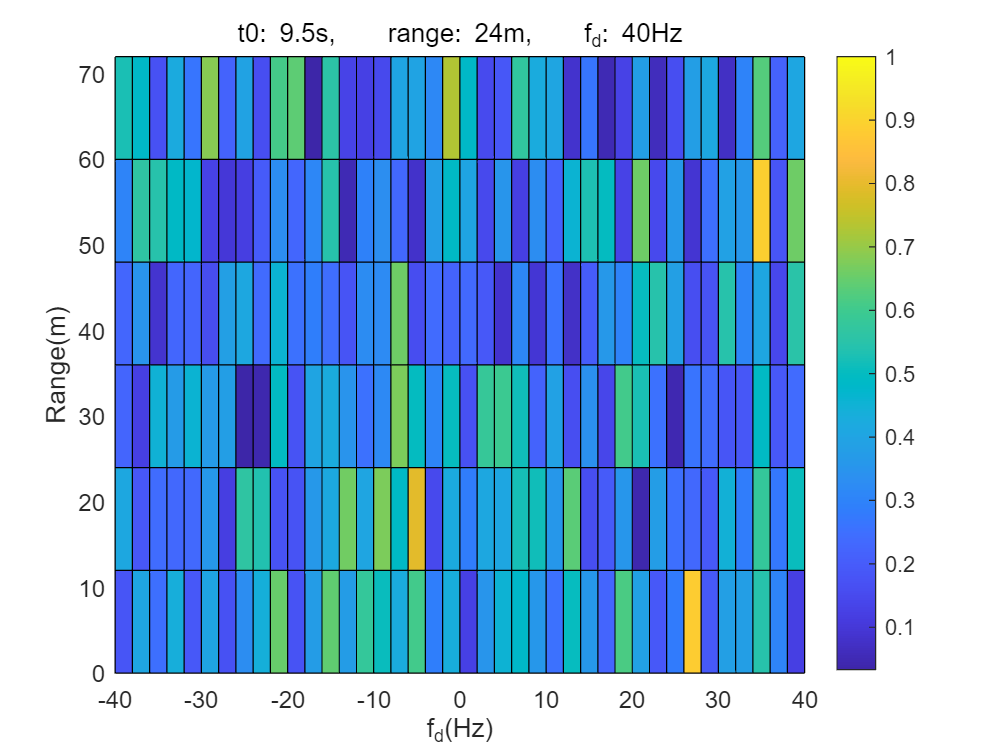

    save("cors_Quicker4/" + sampling_points + "/cors" + (t0 / 0.1 + 1) + ".mat", "cors");
end

sampling_points = 100000;
hiti = 0;
hitj = 0;
acci = 1;
accj = 1;
for index = 1:96
    dataStruct1 = load("cors/cors" + index + ".mat");  
    cors1 = dataStruct1.cors;

    dataStruct2 = load("cors_Quicker4/" + sampling_points + "/cors" + index + ".mat");
    cors2 = dataStruct2.cors;

    max1 = -1;
    maxi1 = -1;
    maxj1 = -1;

    max2 = -1;
    maxi2 = -1;
    maxj2 = -1;

    for i = 1:7
        for j = 1:41
            if (cors1(i, j) > max1)
                max1 = cors1(i, j);
                maxi1 = i;
                maxj1 = j;
            end

            if (cors2(i, j) > max2)
                max2 = cors2(i, j);
                maxi2 = i;
                maxj2 = j;
            end
        end
    end

    if (maxi1 == maxi2)
        hiti = hiti + 1;
    else
        acci = acci - abs(maxi1 - maxi2) / (7 * 96);
    end

    if (maxj1 == maxj2) 
        hitj = hitj + 1;
    else
        accj = accj - abs(maxj1 - maxj2) / (41 * 96);
    end
end

disp("hit_tau: " + (hiti / 96 * 100) + "%")

hit_tau: 91.6667%


disp("acc_tau: " + (acci * 100) + "%")

acc_tau: 97.9167%


disp("hit_fd: " + (hitj / 96 * 100) + "%")

hit_fd: 87.5%


disp("acc_fd: " + (accj * 100) + "%")

acc_fd: 98.3232%
